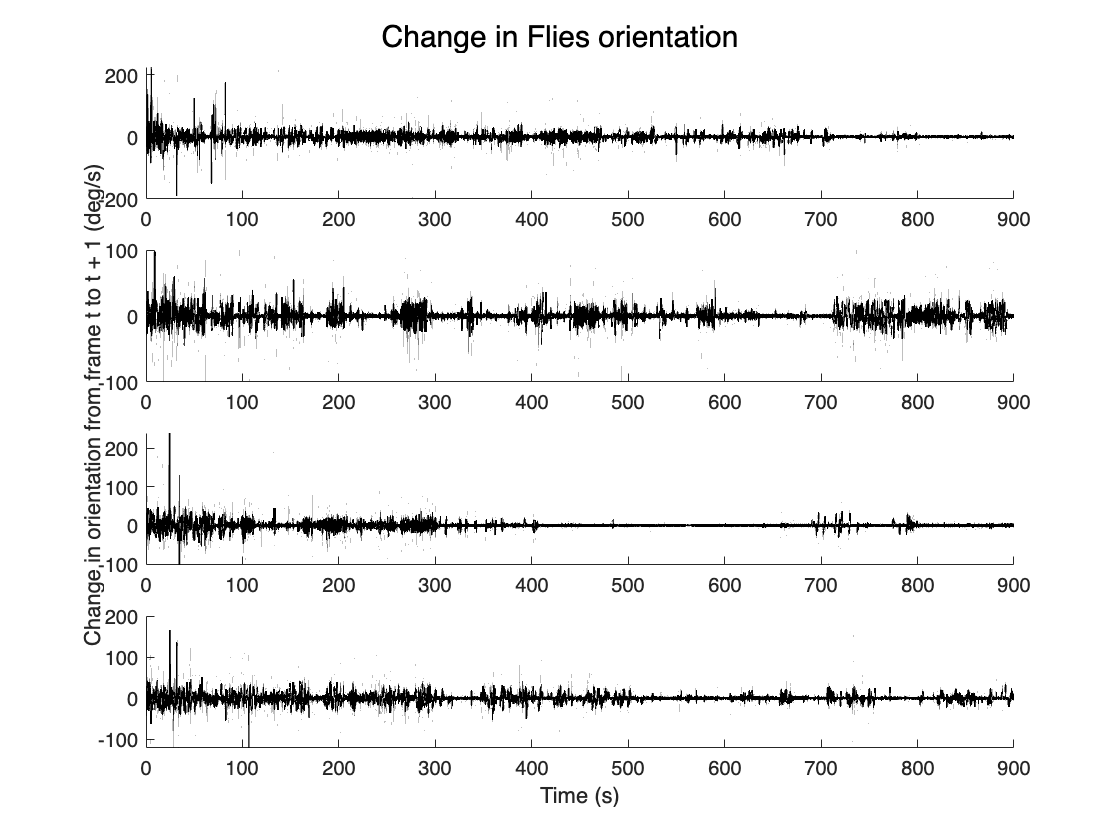

cd('/Volumes/otopaliklab/flydisco_data/2024-08-15/fourbubble_multibubble__whiteOnly_CS4-1_UASChrimsonVenusX0070_20240815T155544')
load ("registered_trx.mat")
load ("movie-track.mat")
addpath('perframe/');

%%%for perframe OF ONLY MALES %%
load ("perframe/ddcenter.mat") %load perframe features 
time = trx.timestamps;
new_time = linspace(min(time), max(time), length(data{2}));

%%add IDs
males_IDs= [1 6 11 18];


%%%%to only plot males perframes
figure;
for i = 1:4  % Loop over 4 subplots
    subplot(4, 1, i);  % Create a 4x1 grid of subplots
    
    % Plot the chaser's data in black
    plot(new_time, data{males_IDs(i)}, 'k-', 'LineWidth', 1);

% Change sgtitle for each parameter
 % Set the x-axis limits
    set(gca, 'xlim', [0 900]);
    box off;  % Remove the box around the plot
    hold off;  % Release the hold for the next subplot

sgtitle('Change in Flies orientation')
han = axes(gcf,'Visible','off');
han.YLabel.Visible = 'on';
% Change ylabel for each parameter
ylabel(han, 'Change in orientation from frame t to t + 1 (deg/s)');
han.XLabel.Visible = 'on';
xlabel(han, 'Time (s)');
end

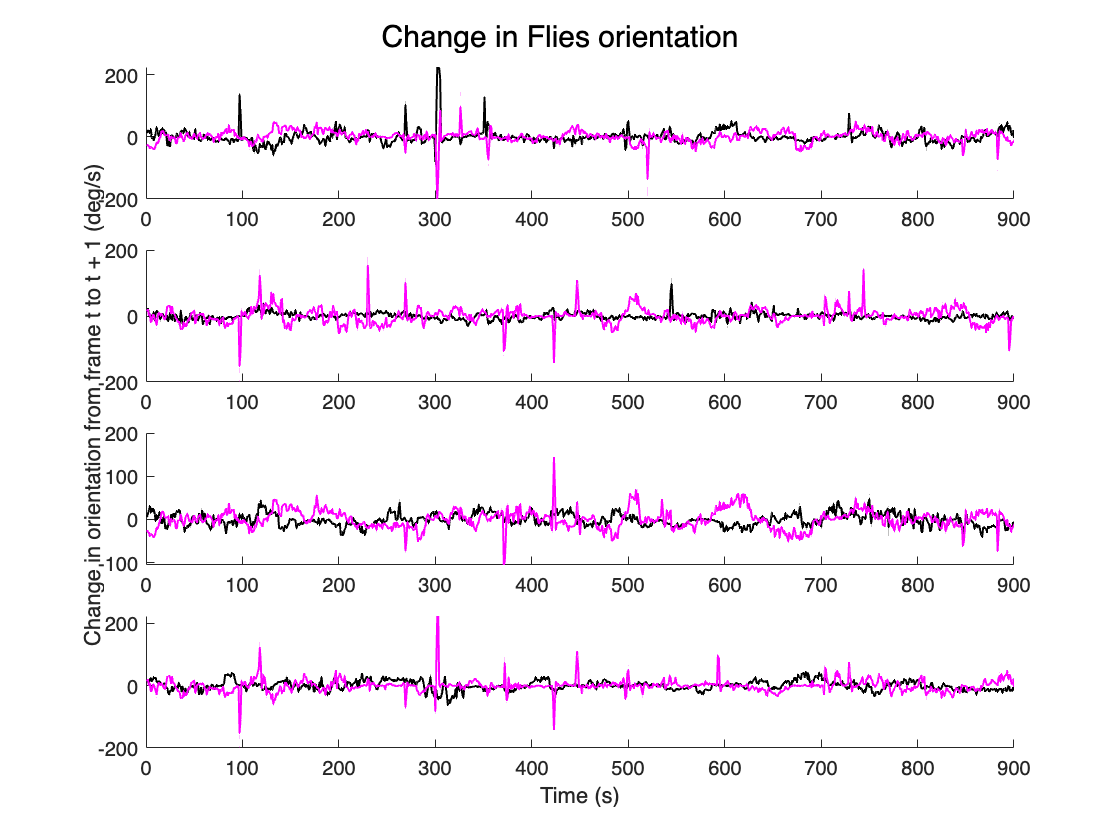




%%%FOR PERFRAMES 4 SUBPLOTS ALL ANIMALS

figure;
males_IDs = [1, 6, 11, 18];  % IDs for males
females_IDs = [2, 3, 4, 5, 7, 8, 9, 10, 12, 13, 14, 15, 16, 17, 19, 20];  % IDs for females

for i = 1:4  % Loop over 4 subplots
    subplot(4, 1, i);  % Create a 4x1 grid of subplots
    
    % Plot the chaser's data in black
    plot(data{males_IDs(i)}, 'k-', 'LineWidth', 1);
    hold on;  % Hold on to overlay the next plots
    
    % Plot the first runner's data in blue
    plot(data{females_IDs(i)}, 'c-', 'LineWidth', 1);
    
    % Plot the second runner's data in red
    plot(data{females_IDs(i)}, 'm-', 'LineWidth', 1);

    % Set the x-axis limits
    set(gca, 'xlim', [0 900]);
    box off;  % Remove the box around the plot
    hold off;  % Release the hold for the next subplot

    sgtitle('Change in Flies orientation')
han = axes(gcf,'Visible','off');
han.YLabel.Visible = 'on';
% Change ylabel for each parameter
ylabel(han, 'Change in orientation from frame t to t + 1 (deg/s)');
han.XLabel.Visible = 'on';
xlabel(han, 'Time (s)');
end

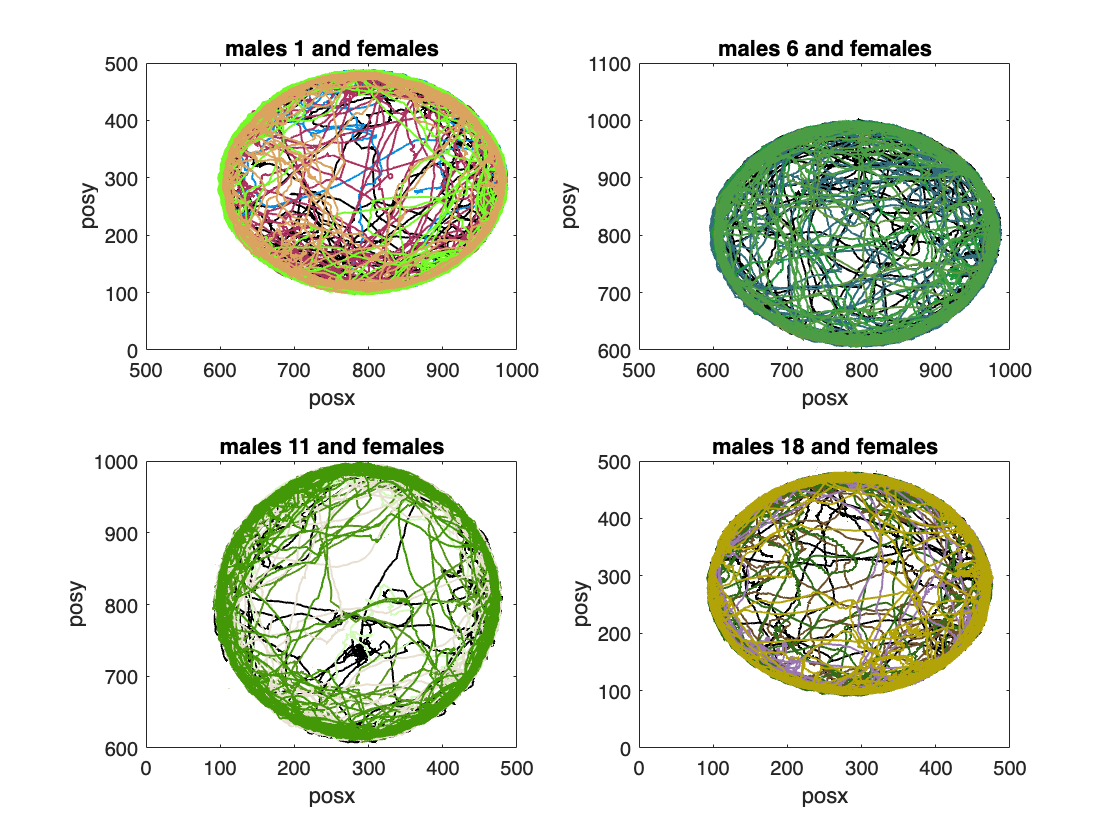


%%%%%%%TO PLOT TRAJECTORIES OF MALES AND FEMALES 
%assign posx and posy
posx=trk.data(:,:,1); %remember to first load the video-track.mat on workspace
posy=trk.data(:,:,2);

figure;
males_IDs = [1, 6, 11, 18];  % IDs for males
females_IDs = [2, 3, 4, 5, 7, 8, 9, 10, 12, 13, 14, 15, 16, 17, 19, 20];  % IDs for females


for i = 1:4  % Loop over 4 subplots
    subplot(2, 2, i);  % Create a 2x2 grid of subplots
    
    % Plot the male's trajectory
    plot(posx(males_IDs(i), :), posy(males_IDs(i), :), 'k-', 'LineWidth', 1);
    hold on;  % Hold the plot to overlay the next plots on the same subplot
    
    % Calculate females indices for the current male
    start_idx = (i-1)*4 + 1;  % Start index for females (4 runners per chaser)
    end_idx = start_idx + 3;  % End index for females
    
    % Loop to plot 4 females' trajectories on each subplot
    for j = start_idx:end_idx
        plot(posx(females_IDs(j), :), posy(females_IDs(j), :), 'Color', rand(1,3), 'LineWidth', 1); % Random color for each runner
    end
    
    hold off;  % Release the hold for the next subplot
    
    % Set labels and title if needed
    xlabel('posx');
    ylabel('posy');
    title(['males ' num2str(males_IDs(i)) ' and females']);
end

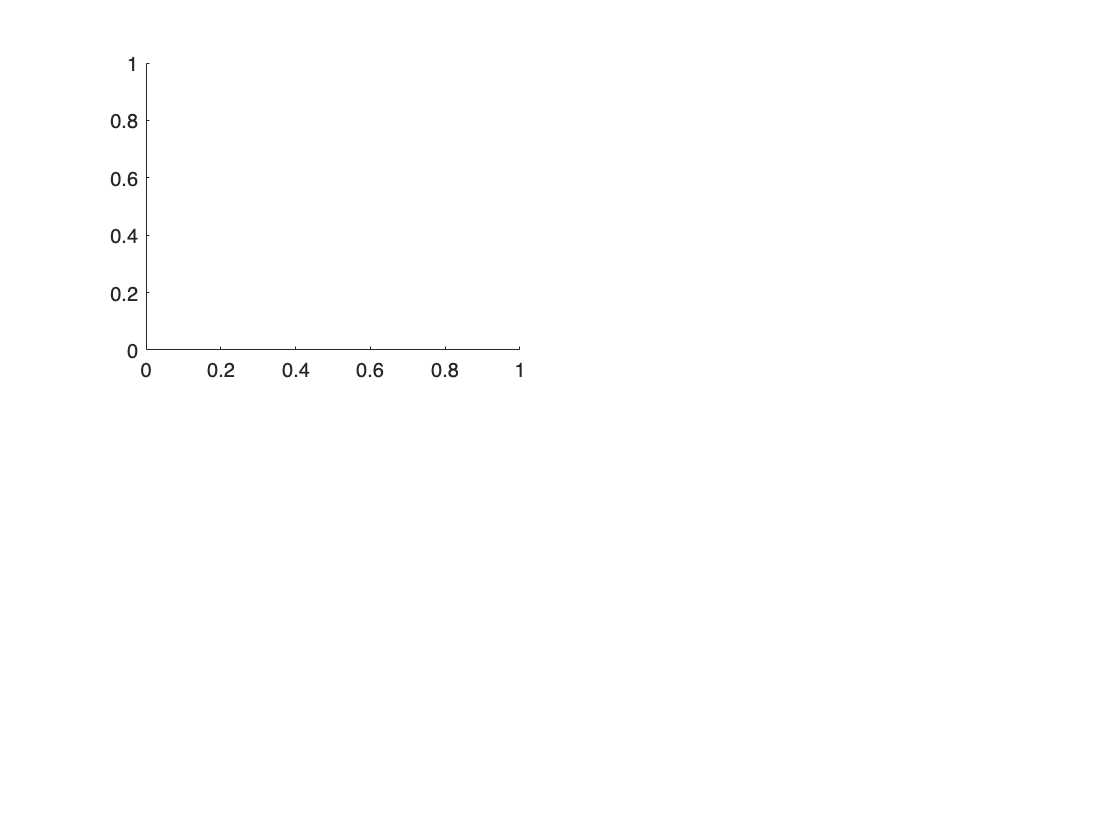

Error using plot
Invalid data argument.



%%%%%%%test

figure;
males_IDs = [1, 6, 11, 18];  % IDs for males
females_IDs = [2, 3, 4, 5, 7, 8, 9, 10, 12, 13, 14, 15, 16, 17, 19, 20];  % IDs for females


for i = 1:4  % Loop over 4 subplots
    subplot(2, 2, i);  % Create a 2x2 grid of subplots
    
    % Plot the male's trajectory
    plot(data(males_IDs(i), :),'k-', 'LineWidth', 1);
    hold on;  % Hold the plot to overlay the next plots on the same subplot
    
    % Calculate females indices for the current male
    start_idx = (i-1)*4 + 1;  % Start index for females (4 runners per chaser)
    end_idx = start_idx + 3;  % End index for females
    
    % Loop to plot 4 females' trajectories on each subplot
    for j = start_idx:end_idx
        plot(data(females_IDs(j), :), 'Color', rand(1,3), 'LineWidth', 1); % Random color for each runner
    end
    
    hold off;  % Release the hold for the next subplot
    
    % Set labels and title if needed
    xlabel('posx');
    ylabel('posy');
    title(['males ' num2str(males_IDs(i)) ' and females']);

    sgtitle('Change in Flies orientation')
han = axes(gcf,'Visible','off');
han.YLabel.Visible = 'on';
% Change ylabel for each parameter
ylabel(han, 'Change in orientation from frame t to t + 1 (deg/s)');
han.XLabel.Visible = 'on';
xlabel(han, 'Time (s)');
end